clear all;
f = @(x, y) x + y;
h = 0.1;
x = 0:0.1:10;
y(1) = 1;
prevY = y(1);

format long;

tol = 10^-5;
maxiter = 10000

maxiter =        10000



cnt = 1;

for n = 1:length(x)-1
    yval = [];
    yval(1) = prevY;
    for m = 1:maxiter
        yval(m+1) = y(n) + (h/2) * (f(x(n), y(n)) + f(x(n+1), yval(m)));
        if abs(yval(m) - yval(m+1)) < tol
            break;
        end
    end
    prevY = yval(end);
    y(n+1) = yval(end);
end
y

y = 	1.0e+04 *

   0.000100000000000   0.000111052628125   0.000124321321676   0.000140039350625   0.000158464539669   0.000179881852942   0.000204606250788   0.000232985847266   0.000265405400004   0.000302290167426   0.000344110171981   0.000391384912153   0.000444688570459   0.000504655769662   0.000571987934901   0.000647460325516   0.000731929807068   0.000826343441466   0.000931747981313   0.001049300363664   0.001180279308381   0.001326098137380   0.001488318943252   0.001668668302881   0.001869054436896   0.002091586479408   0.002338595578644   0.002612658266850   0.002916622290190   0.003253635157576   0.003627175694642   0.004041088919190   0.004499624587729   0.005007479799555   0.005569846085458   0.006192461453147   0.006881667911130   0.007644475047751   0.008488630302746   0.009422696635808   0.010456138370798   0.011599416076177   0.012864091432856   0.014262943140773   0.015810095026154   0.017521157633750   0.019413384723526   0.021505846240677   0.023819619493016   0

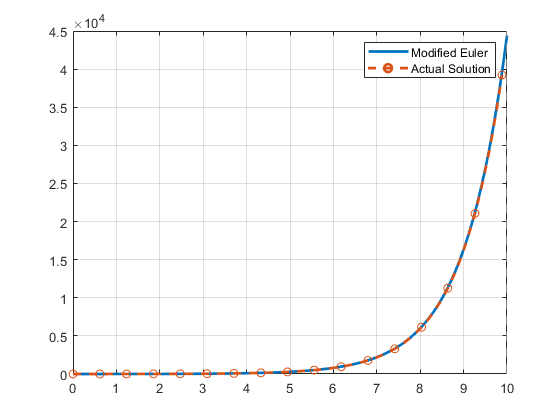

plot(x, y, '-', 'LineWidth', 2)
grid on;
hold on;

ysol = dsolve('Dy=x+y', 'y(0)=1', 'x');
fplot(ysol, [x(1) x(end)],'--o' ,'LineWidth', 2);

legend('Modified Euler', 'Actual Solution')

hold off;